# **2108332 Adjustment Computation**

## **LAB 8** Non-linear Model

**ชื่อ-นามสกุล: วสุพล คล้ายขำ**

**รหัสประจำตัวนิสิต: 6631137221**

- **โครงข่ายสามเหลี่ยมในภาพที่ 1 มีจุดที่ทราบค่าพิกัดคือจุด BM1, BM2 และ BM3 ดังแสดงในภาพ ส่วนจุด A และ B เป็นจุดที่ต้องการทราบค่าพิกัด**

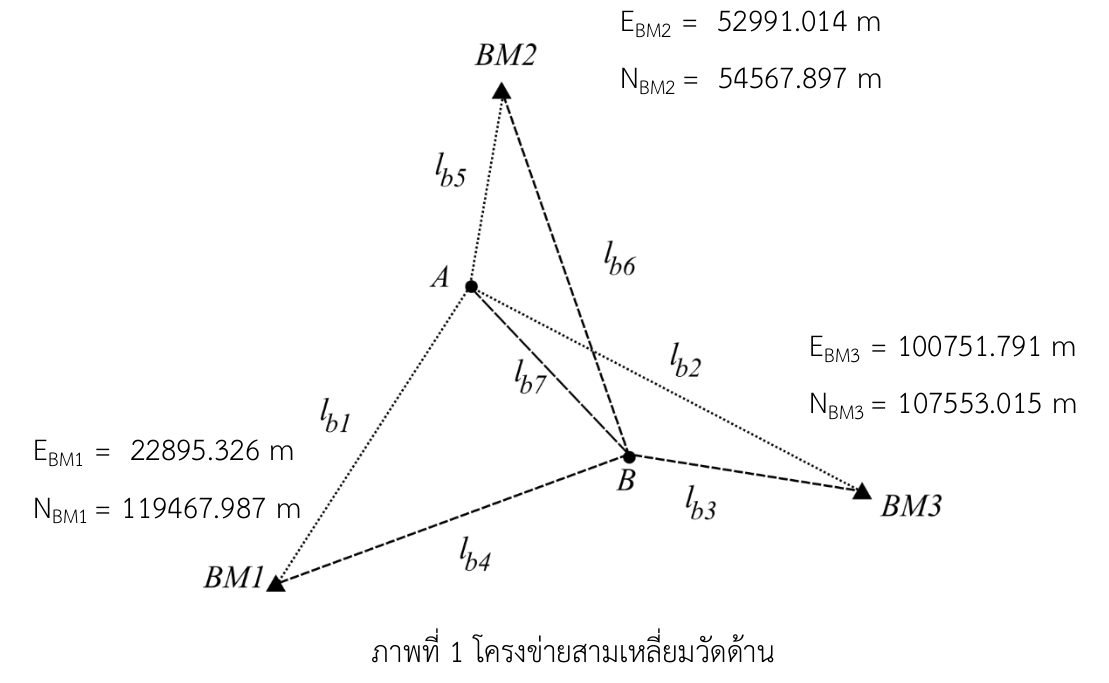

#### ในการสำรวจมีการวัดระยะระหว่างจุด ดังแสดงในตารางต่อไปนี้

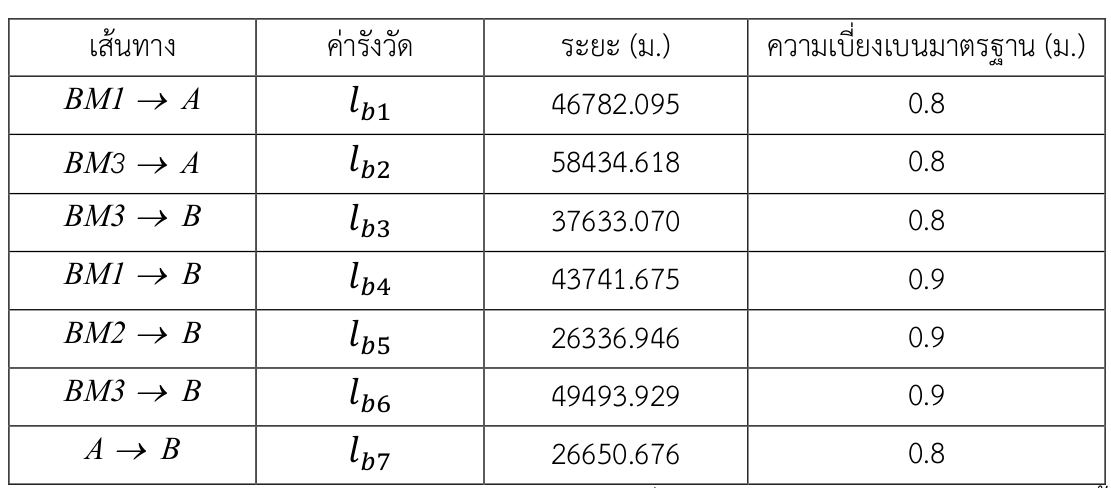

กำหนดให้ค่ารังวัดเป็นอิสระต่อกันและมีน้ำหนักเท่ากัน ให้เขียนสคริปต์เพื่อปรับแก้ค่ารังวัดโดยวิธีสมการค่ารังวัด ในการคำนวณให้ใช้ค่า $E_{A0} = 49000\spacem, N_{A0} = 81000\spacem, E_{B0} = 63000\spacem, N_{B0} =103000\spacem$ เป็นค่าประมาณของค่าพิกัดของจุด A และ B $$(E_{A}, N_{A}, E_{B}, N_{B})$$ สคริปต์ต้องแสดงผล 2 ส่วนคือ ค่าพิกัดของจุด A และ B และค่ารังวัดที่ปรับแก้แล้ว

clc
clear
format long g
syms EA NA EB NB
EA0 = 49000; NA0 = 81000;
EB0 = 63000; NB0 = 103000;
EBM1 = 22895.326; NBM1 = 119467.987;
EBM2 = 52991.014; NBM2 = 54567.897;
EBM3 = 100751.791; NBM3 = 107553.015;
lb = [46782.095;58434.618;37633.070;43741.675;26336.946;49493.929;26650.676];

P = [1/0.8^2;1/0.8^2;1/0.8^2;1/0.9^2;1/0.9^2;1/0.9^2;1/0.8^2];
p = diag(P);

la1 = sqrt((EA - EBM1)^2 + (NA - NBM1)^2);
la2 = sqrt((EA - EBM3)^2 + (NA - NBM3 )^2);
la3 = sqrt((EB - EBM3)^2 + (NB - NBM3)^2);
la4 = sqrt((EB - EBM1)^2 + (NB - NBM1)^2);
la5 = sqrt((EA - EBM2)^2 + (NA - NBM2)^2);
la6 = sqrt((EB - EBM2)^2 + (NB - NBM2)^2);
la7 = sqrt((EB - EA)^2 + (NB - NA)^2);

J = jacobian([la1 la2 la3 la4 la5 la6 la7],[EA NA EB NB]);
J = subs(J,[EA NA EB NB],[EA0 NA0 EB0 NB0]);

F0 = [subs(la1,[EA NA EB NB],[EA0 NA0 EB0 NB0]);
    subs(la2,[EA NA EB NB],[EA0 NA0 EB0 NB0]);
    subs(la3,[EA NA EB NB],[EA0 NA0 EB0 NB0]);
    subs(la4,[EA NA EB NB],[EA0 NA0 EB0 NB0]);
    subs(la5,[EA NA EB NB],[EA0 NA0 EB0 NB0]);
    subs(la6,[EA NA EB NB],[EA0 NA0 EB0 NB0]);
    subs(la7,[EA NA EB NB],[EA0 NA0 EB0 NB0]);];
X0 = [EA0;NA0;EB0;NB0];
Fx = F0 - J * X0;
Lf = Fx - lb;
Xa = double(- inv(J' * p * J) * J' * p * Lf);
fprintf('EA = %f',Xa(1))

EA = 48911.164298

fprintf('NA = %f',Xa(2))

NA = 80586.598863

fprintf('EB = %f',Xa(3))

EB = 63400.532113

fprintf('NB = %f',Xa(4))

NB = 102955.871608

v = double(J * Xa + Lf);

la = lb + v

la =           46781.3292759339
          58433.9890642738
           37632.988803026
          43741.3909781021
          26336.2042047083
          49493.3653435848
          26651.0804005656


#### 2. ต้องการทราบความยาวด้านทั้งหมดของรูปสามเหลี่ยมมุมฉากในภาพที่ 2

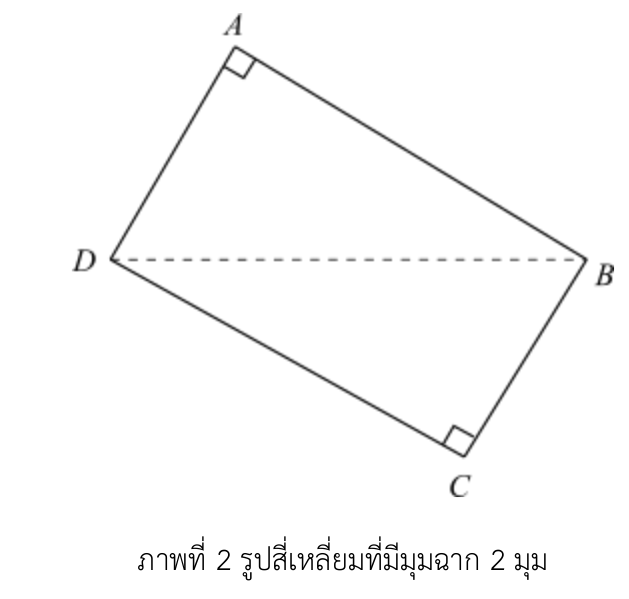

#### ค่ารังวัดมีดังนี้

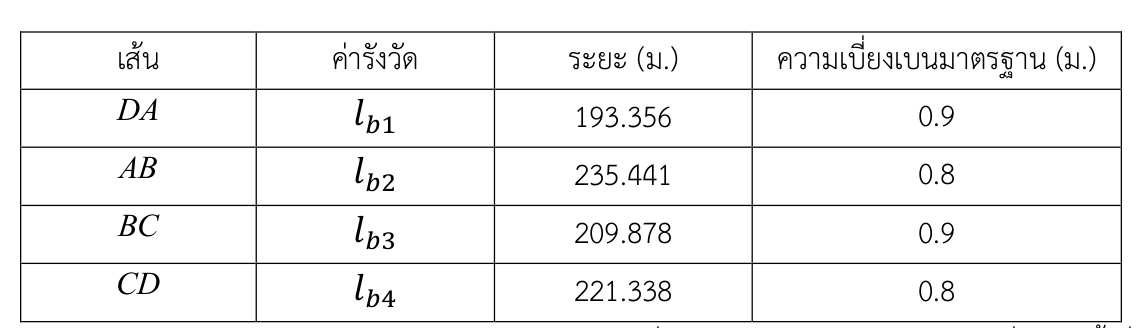

#### กำหนดให้ค่ารังวัดไม่มีสหสัมพันธ์และมีน้ำหนักเท่ากัน ให้เขียนสคริปต์เพื่อปรับแก้ค่ารังวัดโดยวิธีสมการเงื่อนไข สคริปต์ต้องแสดงผลค่ารังวัดที่ปรับแก้แล้ว

clc
clear
format long g
lb = [193.356;235.441;209.878;221.338];

P = [1/0.9^2;1/0.8^2;1/0.9^2;1/0.8^2];
p = diag(P);

syms la1 la2 la3 la4;

f = la1^2 + la2^2 - la3^2 - la4^2;

J = jacobian(f,[la1 la2 la3 la4]);
J = subs(J,[la1 la2 la3 la4],[lb(1) lb(2) lb(3) lb(4)]);

F0 = subs(f,[la1 la2 la3 la4],[lb(1) lb(2) lb(3) lb(4)]);
v = double(-inv(p) * J' * inv(J * p^-1 * J') * F0);
La = lb + v

La =           193.485899483943
          235.565976057822
          209.737000786678
          221.220510052683
